# Part 3: Anomaly Detection with Statistical Approaches and Machine Learning

# 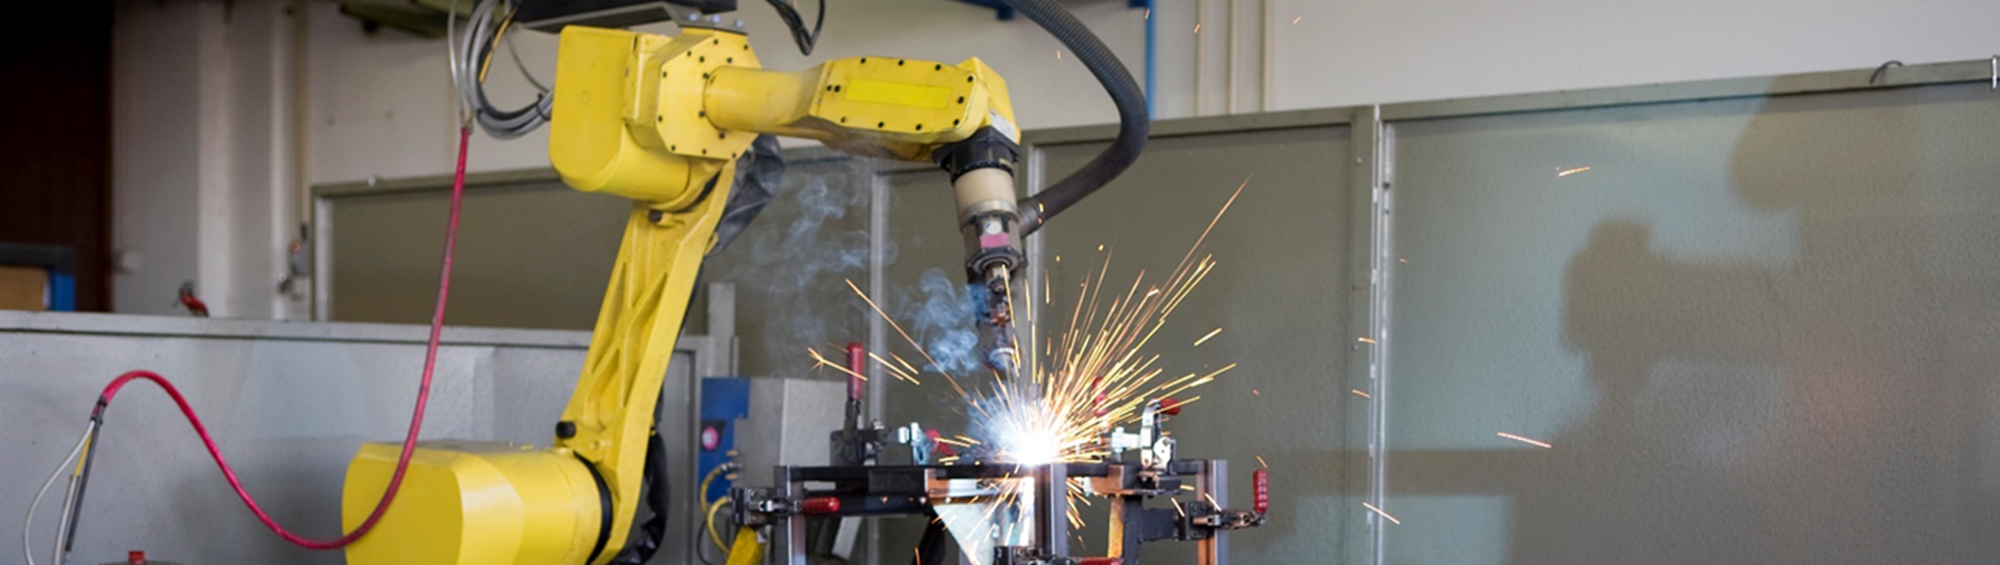

This example illustrates various approaches to anomaly detection available in the [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html)™. We use the same operating data collected from vibration sensors before and directly after a scheduled maintenance period. Since the focus of this example is on modeling approaches, we use the same features that were computed from raw data using the [Diagnostic Feature Designer App](https://www.mathworks.com/help/predmaint/gs/explore-features-in-diagnostic-feature-designer.html).

We then use the trained model to reconstruct the features extracted from new data. If the model reconstructs the features well, it indicates that the machine is operating normally. If the reconstruction surpasses an error threshold, this indicates that the machine is acting abnormally and requires maintenance.

## **Prepare Data for Machine Learning**

In the first section, we extracted 12 highly ranked features from a small subset of the larger dataset of 17,642 signals. While large data sets are needed for deep learning, the advantage of modeling your process data with machine learning is that you can build good models with much less data. To illustrate that, we'll work with just 10% of the full set in this exercise.

Like in the second section, we use the data before maintenance as a stand-in for anomalies--that's about 40% of the data. After maintenance the machine is healthy and produces "normal"  data. You have much less "abnormal" data at your disposal, but good news is that most anomaly detection approaches assume exactly that: that you primarily have normal data.

load("FeatureEntire.mat")

% Take just ~10% of the data
nAll = size(featureAll,1);

subsetIdx = randi([1 nAll],round(nAll*0.1),1);
featureSmall = featureAll(subsetIdx,:);

% divide subset into train and (held out) test
idxSmall = cvpartition(featureSmall.label,'holdout',0.2);
featSmallTrain = featureSmall(idxSmall.training,:);
featSmallTest = featureSmall(idxSmall.test,:);

% establish ground truth on anomalies in test data ('Before" maintenance)
trueAnomaliesTest = renamecats(featSmallTest.label,["Before","After"],["Anomaly","Healthy"]);


## Supervised Approach: Train Classifiers

The original dataset is fairly balanced, in the same order samples of "after" (normal) and "before" maintenance, representing abnormal operating condition. For use cases where you have lots of labeled data in both conditions, you can simply apply standard supervised learning and build classifiers. The chart below illustrates the relationship between amount of labeled data available and some possible approaches to anomaly detection.

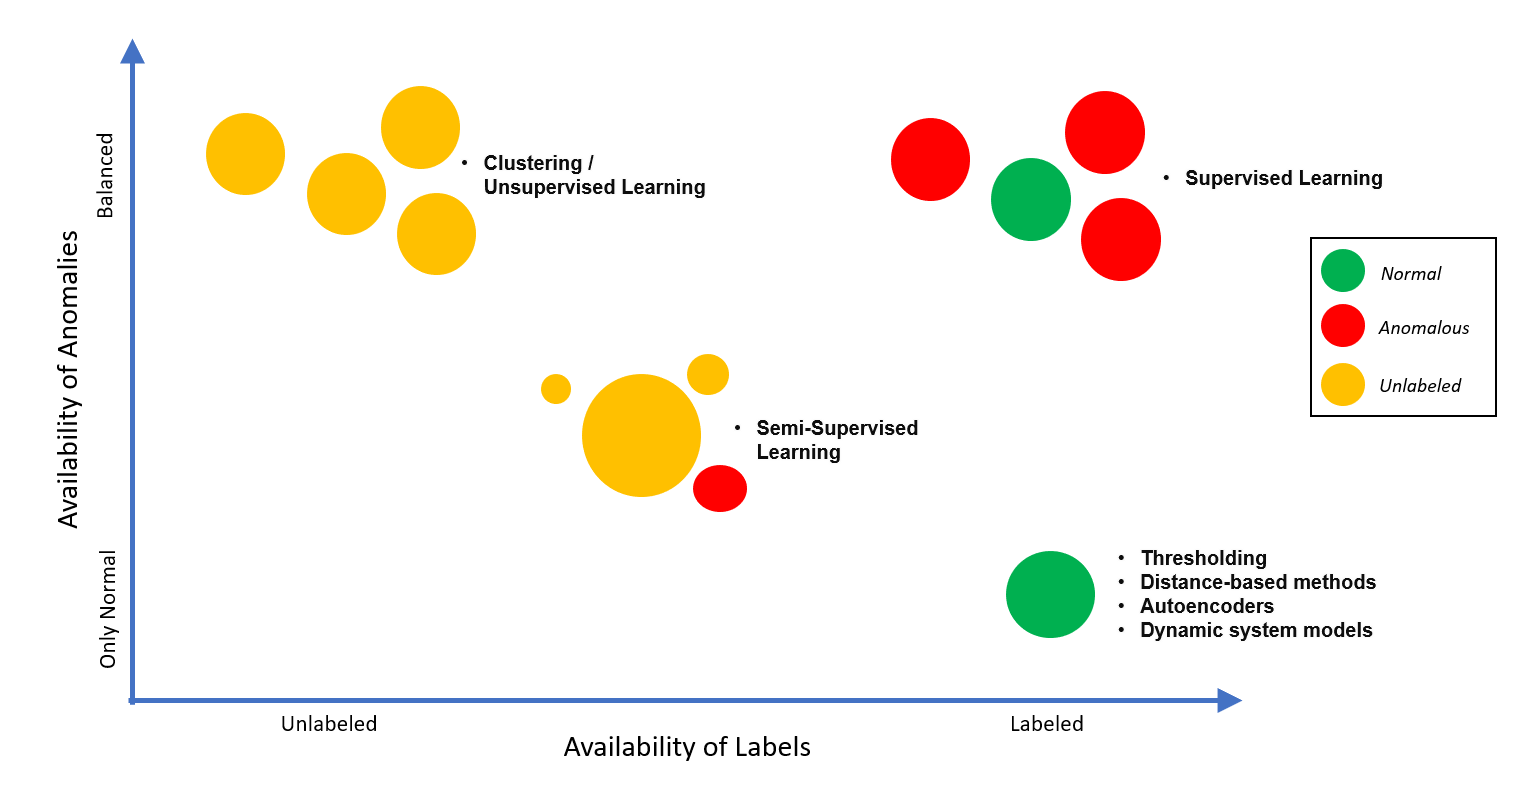

For this data set, we are in the upper right quadrant where supervised learning is appropriate. Several machine learning algorithms achieve good classification accuracy - indicating that the features we extracted earlier are pretty good. Below we show accuracy on the held-out ("small") test set.

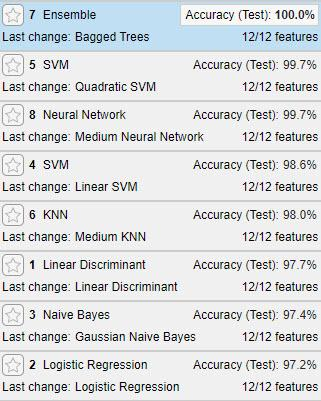

For the rest of this script, we pretend that we have primarily normal data available (by removing the 'Before" data from the training set), and demonstrate how to apply the methods mentioned in the lower right quadrant.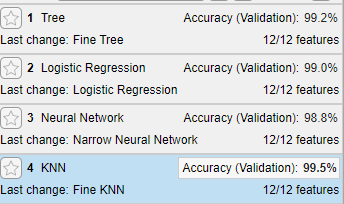

## Statistical (Machine Learning) Approaches to Anomaly Detection

### Detect Anomalies with One-class SVM

Support Vector Machines are powerful classifiers, and their variant training only one class models the "normal" data and works pretty well for identifying abnormalities as being "far" from how the normal data looked.

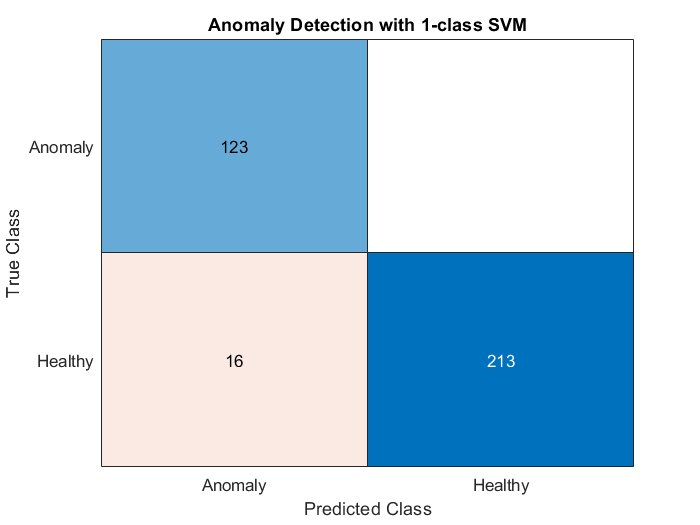

% we train on the "normal" (healthy) model data only
healthyIdx = featSmallTrain.label=='After';
trainHealthy = featSmallTrain(healthyIdx,2:13);   % can safely skip labels column since all are 'After' (maintenance)
trainHealthyN = size(trainHealthy,1);

% train one-class SVM
mdlSVM = fitcsvm(trainHealthy,ones(trainHealthyN,1),'Standardize',true,'OutlierFraction',0);

% apply to "small" test data (which has both anomalies and healthy data)
[~,scoreSVM] = predict(mdlSVM,featSmallTest(:,2:13));
isanomalySVM = scoreSVM<0;
predSVM = categorical(isanomalySVM, [1, 0], ["Anomaly", "Healthy"]);

confusionchart(trueAnomaliesTest,predSVM,"Title","Anomaly Detection with One-class SVM");

We can see the one-class SVM does pretty well, all abnormal samples are identified ('Before' maintenance), and only 7% of the "healthy" ones are miscassified

### Detect Anomalies with Isolation Forest

The decision trees of an isolation forest isolate each observation in a leaf. How many decisions a sample passes through to get to its leaf is a measure of how complicated it was to isolate it from the others. The average depth of trees for a specific sample is used as their anomaly score, and returned by the [iforest](https://mathworks.com/help/stats/iforest.html) function (available in R2021b).

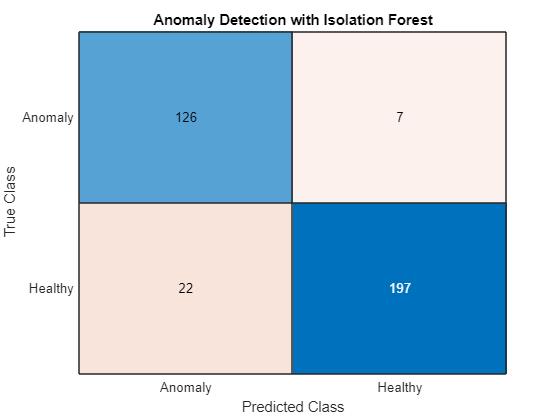

% train on normal (healthy) data only. Need to tune the ContimationFraction!
[mdlIF,~,scoreTrainIF] = iforest(trainHealthy,'ContaminationFraction',0.1);

[isanomalyIF,scoreTestIF] = isanomaly(mdlIF,featSmallTest(:,2:13));
predIF = categorical(isanomalyIF, [1, 0], ["Anomaly", "Healthy"]);

confusionchart(trueAnomaliesTest,predIF,'Title','Anomaly Detection with Isolation Forest');

To better understand how the isolation forest works, it can be helpful to visualize the distribution of anomaly scores.

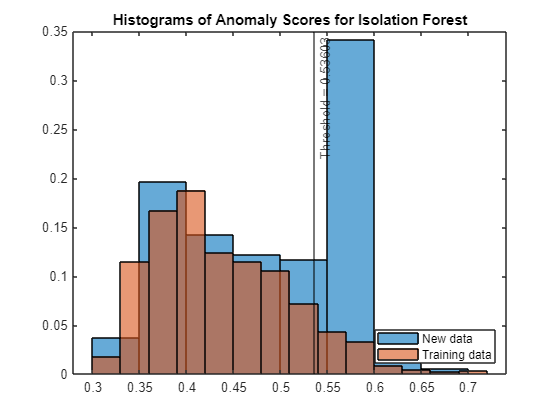

% let's check whether or not the abnomaly score distributions for train vs test data match
figure;
histogram(scoreTestIF,Normalization="probability");
hold on;
histogram(scoreTrainIF,Normalization="probability");
xline(mdlIF.ScoreThreshold,"k-", join(["Threshold =" mdlIF.ScoreThreshold]))
legend("New data","Training data",Location="southeast")
title("Histograms of Anomaly Scores for Isolation Forest")
hold off;

The big difference in the distribution of training and test data is the latter contains "anomalous" data - more than 30% - while the training didn't, and we set the threshold just right to correctly identify the bulk of that anomalous data.  

If you had more features, like the hundreds of wavelet features that you typically get from the wavelet scattering approach, the isolation forest might outperform the one-class SVM. (*Q: should we include wavelet scattering?)*

### Detect Anomalies with Robust Covariance

Another statistical approach for detection of anomalies leans on estimating robust covariances (and means), and identifying anomalies (outliers) as being on the fringes of the distribution. Robust estimators handle data that contains outliers and deviate from the assumption of multivariate normality. [robustcov](https://www.mathworks.com/help/stats/robustcov.html) has been available since R2016a.

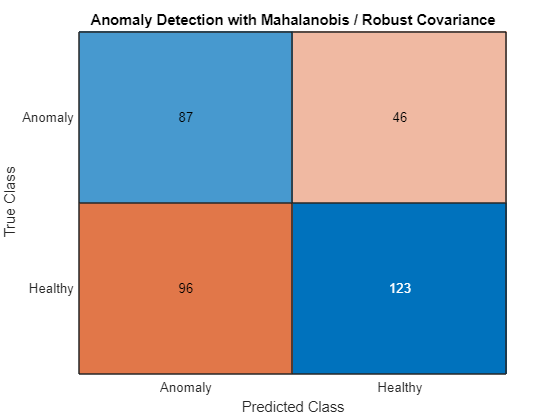

featSmallTrainM = table2array(featSmallTrain(:,2:13));    % robustcov expects input as matrix
featSmallTestM = table2array(featSmallTest(:,2:13)); 
outlierFraction = 1 - trainHealthyN / size(featSmallTrainM,1);

% compute robust covariance on both normal and (typically only a little)
% abnormal data - which is not the case for this data!
[sigma,mu,mahalDistRobust,~] = robustcov(featSmallTrainM, OutlierFraction=outlierFraction);
sigRobustThresh = sqrt(chi2inv(1-outlierFraction,size(featSmallTrainM,2)));

% identify anomalies on new (test) data with Mahalanobis distance
scoreTestMahal = pdist2(featSmallTestM,mu,"mahalanobis",sigma);
isanomalyMahal = scoreTestMahal > sigRobustThresh;
predMahal = categorical(isanomalyMahal, [1, 0], ["Anomaly", "Healthy"]);

confusionchart(trueAnomaliesTest,predMahal,'Title','Anomaly Detection with Mahalanobis / Robust Covariance');

Robust covariance estimation is not working well on this data, but remember it was atypical in that it was almost balanced between the two conditions.

### Visualize various Anomaly Detection Methods

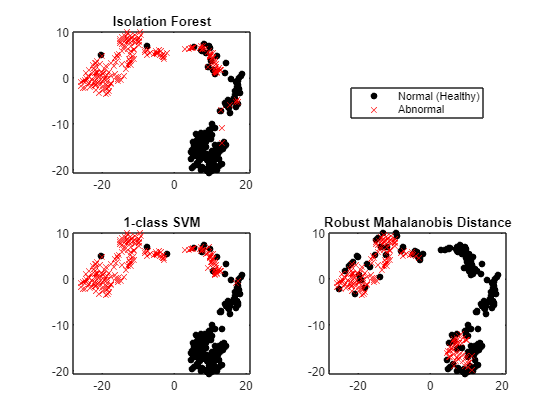

% compare the various anomaly detection methods visually, using t-SNE to
% visualize the 13-dimensional feature space
rng("default") % For reproducibility
T = tsne(featSmallTestM);

figure;
tiledlayout(2,2)
nexttile
gscatter(T(:,1),T(:,2),predIF,"kr",".x",[],"off")
title("Isolation Forest")
nexttile(3)
gscatter(T(:,1),T(:,2),predSVM,"kr",".x",[],"off")
title("One-class SVM")
nexttile(4)
gscatter(T(:,1),T(:,2),predMahal,"kr",".x",[],"off")
title("Robust Mahalanobis Distance")
l = legend("Normal (Healthy)","Abnormal");
l.Layout.Tile = 2;

We can see that the cluster of abnormal data in the upper left corner, and the cluster of normal data in the lower right, are correctly identified by the One-class SVM and isolation forest, whereas the mahalanobis-distance based threshold didn't.

### Apply Clustering to detect Anomalies

You can also apply clustering to identify groups in your data, and relate which of those groups align with normal versus abnormal samples. That's much easier done visually, so let's use the two dimensions which t-SNE summarized the original 12 features, and apply clustering methods - here we use [dbscan](https://www.mathworks.com/help/stats/dbscan.html). It requires some experimentation to find the right settings for the distance parameter epsilon and minimum cluster size.

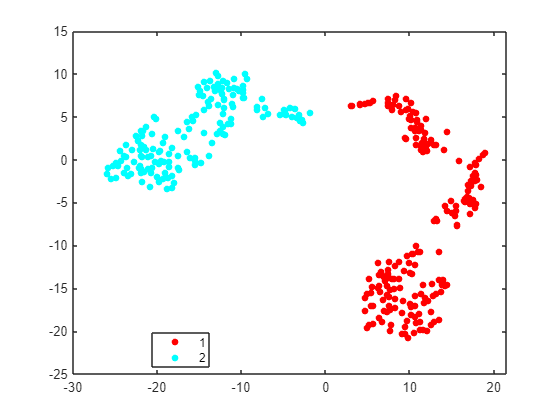

mdlDB = dbscan(T,5,20);
figure;
gscatter(T(:,1),T(:,2),mdlDB);

We found parameter settings that nicely separate the two primary groups of "anomalies" (upper left) versus normal (lower right), but will misclassify the region where both overlap.

## **Summary**

To recap, as example for process data we used timeseries signals from a three-axis accelerometer taken from an industrial machine before and after maintenance. Since the data contained plenty of labelled samples for both conditions, we were able to train classifiers using standard supervised learning, and that method worked best. We also applied four approaches to anomaly detection that need little to no labelled samples of "abnormal":

- One-class SVM

- Isolation Forest (new in R2021b)

- Robust covariance and Mahalanobis distance

- DBSCAN clustering

As next step, you could try other ways to get the features - including automated feature extraction by applying wavelet scattering. That's available in the  [Wavelet Toolbox](https://www.mathworks.com/products/wavelet.html)™

Copyright 2021 The MathWorks, Inc.